# ECSE 343: Numerical Methods for Engineers- Assignement 2

Due Date: 9th March 2021

Student Name: Theodore Janson

Student ID:  260868223

Please type your answers and write you code in this .mlx script. If you choose to provide the handwritten answers, please scan your answers and include those in SINGLE pdf file.

Please submit this **.mlx** file along with the **PDF** copy of this file.

## Question 1: 

a) Prove that $\kappa \;\left(A^{T\;} A\right)={\kappa \left(A\right)}^2 \;$. 

We'll prove that this is only the case for positive definite symmetrical matrices. Assume A is positive definite symmetrical, ie: $A=\;A^{T\;}$ Then $\left(A^{T\;} A\right)=\;$${\left(A^{T\;} A\right)}^{T^T } =\left(A^T A\right)=A^2$

For the other direction, we'll show that if $\left(A^{T\;} A\right)={\left(A\right)}^2$, then $A^{T\;} =\;A$


$$\left(A^T A\right)={\left(A\right)}^2 =\left(\mathrm{AA}\right),\mathrm{so}\;A=A^T \;\mathrm{by}\;\mathrm{cancellation}\;\mathrm{law}\ldotp \;$$


b) Given two orthonormal matrices $U$and $Q$, show that product of these matrices, $\textrm{UQ}$, is also orthonormal.


$$\begin{array}{l}
\mathrm{if}\;\;Q\;\mathrm{and}\;U\;\mathrm{are}\;\mathrm{orthonormal},\mathrm{then}\;Q^T Q=I,\mathrm{and}\;U^T U=I\\
\left.{\left(\mathrm{UQ}\right)}^T {\left(\mathrm{UQ}\right)} =\left(Q^T U^T \right)\left(\mathrm{UQ}\right)=Q^T {\left(U\right.}^T U \right)Q=I
\end{array}$$


c) If A is an invertible matrix and Q is an orthonormal matrix, show that $\kappa \left(\mathrm{QA}\right)=\kappa \left(A\right)\ldotp$

Hint: $\kappa \;\left(A\right)=\frac{\sigma_1 }{\sigma_{n\;} }\;$ (the ratio of the largest and smallest eigen values).

## Question 2: 

(a) **Cholesky factorization **is a popular matrix factorization algorithm analogous to LU decompostion for positive definite matrices. In this case a matrix $\mathit{\mathbf{M}}\in \Re^{N\times N}$ is factored as


$$\mathit{\mathbf{M}}=\mathit{\mathbf{L}}\;{\mathit{\mathbf{L}}}^T$$
                 

Where $\mathit{\mathbf{L}}\in \Re^{N\times N}$ is a lower triangular matrix with real and positive diagonal enteries. 

Note that there are a number of tests/definitions for positive definite matrices. A matrix, $\mathit{\mathbf{M}}$is positive definite if and only if it satisfies the following two conditions,

     1. The matrix $\mathit{\mathbf{M}}$must be sysmterical, i.e. $\mathit{\mathbf{M}}={\mathit{\mathbf{M}}}^{\mathit{\mathbf{T}}}$

     2. ${\mathit{\mathbf{x}}}^{\mathit{\mathbf{T}}} \mathit{\mathbf{M}}\;\mathit{\mathbf{x}}>0$ for  all  $\mathit{\mathbf{x}}\in \Re^{N\times 1}$ ; $\left\|\mathit{\mathbf{x}}\right\|\not= 0$.

An alternative definition/test is that a matrix $\mathit{\mathbf{M}}\in \Re^{N\times N}$is positive definite if and only if it can be written as


$$\mathit{\mathbf{M}}=\mathit{\mathbf{A}}{\mathit{\mathbf{A}}}^{\mathit{\mathbf{T}}}$$
                 

It can be shown (similarly to how we derived the Doolittle algorithm) that the entries of matrix $\mathit{\mathbf{L}}$ are given by the following expression 


$$\textbf{L}_{i,j} = 
\begin{cases}
    \sqrt{ \textbf{M}_{j,j} - \sum_{k=1}^{j-1} \textbf{L}_{j,k}^2 }    ,& \text{if  } i =j\\
    \frac{1}{\textbf{L}_{j,j}} \left(\textbf{M}_{i,j} - \sum_{k=1}^{j-1} \textbf{L}_{i,k} \textbf{L}_{j,k} \right),              & \text{if  } i>j\\
0, & \text{otherwise}
\end{cases}$$


The cost of Cholesky factorization algorithm is rougly half than the LU decompostion. Your task is to implement the Cholesky decomposition alogorithm in the cell below. Note that for Cholesky decomposition pivoting is not required.

*See appendix 2.a)*

Use the cell below to test the Cholesky decompostion code. To test this, compute the Frobenius norm of  $\left.{\left(\mathit{\mathbf{L}}\right.}^{\;} {\mathit{\mathbf{L}}}^T -M\right)\ldotp$

clc;
clear all;

disp('Question 2a')

Question 2a


A = randi(100,5);
M = A'* A;
L = CholeskyDecomposition(M)

L =   129.7343         0         0         0         0
   79.6705   40.6400         0         0         0
   81.5513   56.1951   62.9722         0         0
   66.5745   98.3015   12.4611   16.0739         0
  118.0027   40.0755   48.2862   12.5579   60.7542




Error =  norm(L*L'- M)

Error = 3.6380e-12

 b) Cholesky decompostion can be used to solve the normal eqautions,  ${\mathit{\mathbf{A}}}^{\mathit{\mathbf{T}}} \mathit{\mathbf{A}}\;\mathit{\mathbf{x}}={\mathit{\mathbf{A}}}^{\mathit{\mathbf{T}}\;} \mathit{\mathbf{b}}$ as the matrix $\left({\mathit{\mathbf{A}}}^{\mathit{\mathbf{T}}} \mathit{\mathbf{A}}\right)$ is positive definite. Using Cholesky facotrization scheme $\left({\mathit{\mathbf{A}}}^{\mathit{\mathbf{T}}} \mathit{\mathbf{A}}\right)$ can be factored as ${\mathit{\mathbf{A}}}^{\mathit{\mathbf{T}}} \mathit{\mathbf{A}}\;={\mathit{\mathbf{L}}}^{\;} {\mathit{\mathbf{L}}}^T$. Using this the normal equations become,


$$\mathit{\mathbf{L}}\;{\mathit{\mathbf{L}}}^{\mathit{\mathbf{T}}} \;\mathit{\mathbf{x}}={\mathit{\mathbf{A}}}^{\mathit{\mathbf{T}}\;} \mathit{\mathbf{b}}$$


The above equation consists of the triangular systems, the solution **x **can be obtained by  first solving $\mathit{\mathbf{L}}\;\mathit{\mathbf{y}}={\mathit{\mathbf{A}}}^{\mathit{\mathbf{T}}\;} \mathit{\mathbf{b}}$ using the forward substitution, then by solving the  ${\mathit{\mathbf{L}}}^{\mathit{\mathbf{T}}} \;\mathit{\mathbf{x}}=\mathit{\mathbf{y}}$ using backward subsitution. Implement the Cholesky solver for least squares in the function below. 

You can use your Forward/Backward Substitution from Assignment 1 for bonus marks. Include your code for forward/backward substitution in the Appendix.

*See appendix 2b)*

d) To test the Cholesky Least Squares solver we numerical algorithm we will use a square matrix. Run the cell below to compare  the solution.

A = [12    10     6     5    46;
     79    14    24    17    55;
     39    95    36    65    30;
     25    96    83    74    75;
     41    58     2    65    19]; 
 
B = [45; 35; 58; 12; 10];

disp('Question 2d)')

Question 2d)



%using forward and back substiution
disp(['Solution to Ax = b using forward and back' ...
    'substitution from assignment 1'])

Solution to Ax = b using forward and backsubstitution from assignment 1


disp('There is a bug producing an incorrect result for entry 1')

There is a bug producing an incorrect result for entry 1


x = LeastSquareSolver_Cholesky(A,B)

x =     0.6147
    2.2369
   -1.2640
   -2.2630
    0.8107



%using inverse
disp('Solution obtained using inverse')

Solution obtained using inverse


x = LeastSquareSolver_Cholesky2(A,B)

x =     0.3532
    2.2369
   -1.2640
   -2.2630
    0.8107




% verify your solution
verification = A\B

verification =     0.3532
    2.2369
   -1.2640
   -2.2630
    0.8107


**Question 3: **

Polynomial fitting is one of the many applications of Least-Squares Approximation. Given the experimental data, shown in Table below, 

    
$$\matrix{   Input,, x  | &  x_0  &x_1  & x_2& x_3 &\dots  & x_{m-1}& x_m \cr
Output, y| &  y_0 & y_1& y_2 & y_3 & \dots & y_{m-1}&y_m
}$$


we can fit a $n^{\textrm{th}}$degree polynomial, $p\left(x\right)=a_0 +a_1 x+a_{2\;} x^{2\;} +a_3 x^3 +\cdots +a_{n\;} x^n$. To find the coefficicients,  $\mathit{\mathbf{a}}=\left\lbrack a_{0\;} ,\;\;a_1 ,\;\;a_2 ,\cdots a_n \right\rbrack$, we can solve the linear system shown below. 


$$\underset{\mathit{\mathbf{M}}}{\underbrace{\left\lbrack \begin{array}{ccccc}
1 & x_0  & x_0^2  & \cdots  & x_0^n \\
1 & x_1  & x_1^2  & \cdots  & x_1^n \\
1 & x_{2\;}  & x_{2\;}^2  & \cdots \; & x_{2\;}^n \\
\vdots \; & \vdots  & \vdots  & \ddots \; & \vdots \;\\
1 & x_{m-1}  & x_{m-1}^2  & \cdots  & x_{m-1}^n \\
1 & x_m  & x_m^2  & \cdots \; & x_m^n 
\end{array}\right\rbrack } }$$

$$\underset{\mathit{\mathbf{A}}}{\underbrace{\left\lbrack \begin{array}{c}
a_0 \\
a_1 \\
a_2 \\
\vdots \\
a_n 
\end{array}\right\rbrack } } =\underset{\mathit{\mathbf{y}}}{\underbrace{\left\lbrack \begin{array}{c}
y_0 \\
y_1 \\
y_2 \\
\vdots \\
y_{m-1} \\
y_m 
\end{array}\right\rbrack } }$$


Where $\mathit{\mathbf{M}}$ is a Vandermonde matrix (known to be ill-conditioned). The system $\mathit{\mathbf{M}}\;\mathit{\mathbf{a}}=\mathit{\mathbf{y}}$ can then be solved to compute the coefficients in vector $\mathit{\mathbf{a}}\ldotp$

a) Your first task is to write a function that takes the input data vector $\mathit{\mathbf{x}}$ and degree of the polynomial, then returns the Vadermonde matrix $\mathit{\mathbf{M}}\ldotp$ Complete the function in the cell below.

*See appendix 3.a)*

b) The linear system can be solved using different approaches. In the code below, use the Cholesky decompositon and QR decomposition function to find the polynomial coefficients for the 1st degree polynomial. Explain the results obtained in figure 1.

% Load the Input Data from the provided .mat file 
disp('Question 3b)')

Question 3b)


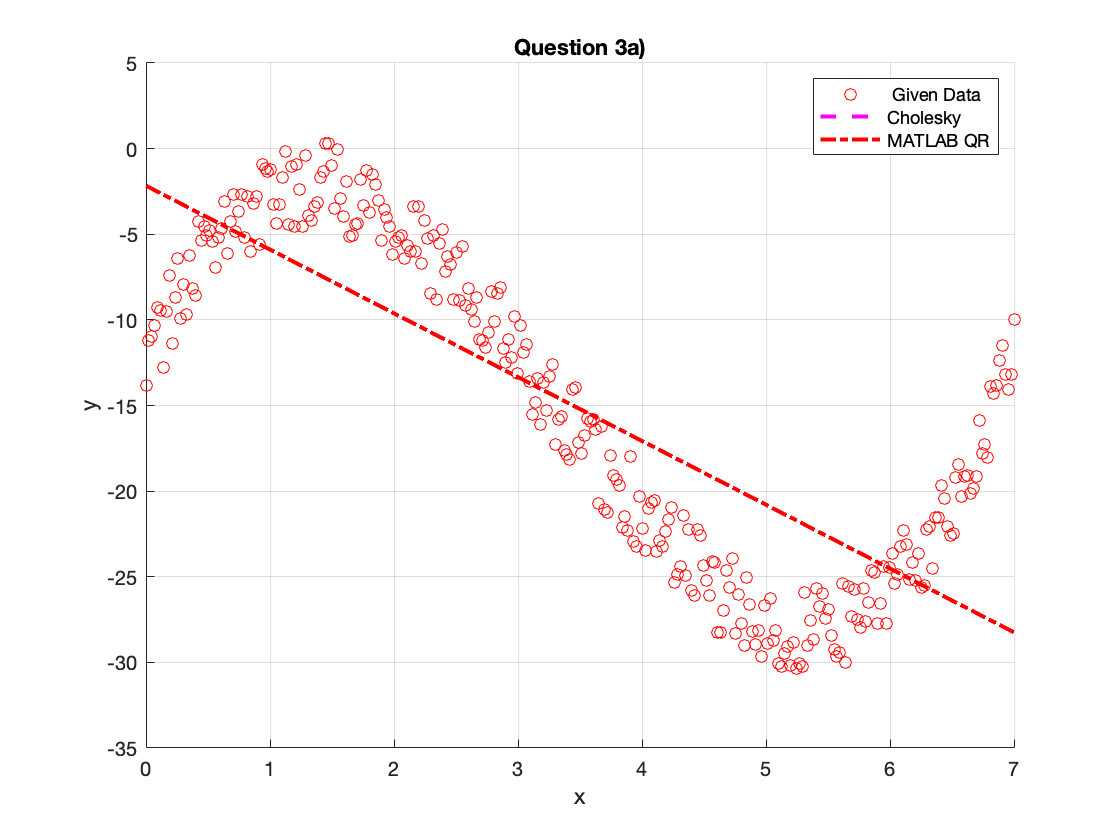

load('Polynomial_Fitting_Data.mat');

% set the degree
deg =  1;
% Define powers 

x = x_given;
y = y_given;

% get Polynomial Matrix 
Mp = PolynomialMatrix(x,deg);


   
   % MATLAB QR Decomposition
   [Q,R] = qr(Mp);
   
            
     Ac = (Mp' * Mp) \ Mp' * y;
   % Name the Coefficeints obtained QR as Ar
     Ar = (Q * R) \ y;
            
   powers = 0:deg;
        
   %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
   x_new = 0:0.01:7;
   x_new = x_new';
   
   fr = zeros(length(x_new),1);
   fc = zeros(length(x_new),1);
   
  
   for I = 1:length(powers)
       fr = fr + Ar(I)*x_new.^powers(I);   
       fc = fc + Ac(I)*x_new.^powers(I);
   end
   %plots
   figure
   hold on
   plot(x,y,'ro')
   plot(x_new,fc,'m--','Linewidth',2)
   plot(x_new,fr,'r-.','Linewidth',2)
   xlabel('x')
   ylabel('y')
   legend(' Given Data','Cholesky','MATLAB QR')
   title('Question 3a)')
   grid on

A polynomial of degree 1 is linear of form mx+b. As shown by the figure titled question 3a), both Matlab QR decomposition and Cholesky decomposition underfit the data which has a sinusoidal distribution. Clearly, a higher order polynomial is needed to more closely approximate a signusoid. Moreover, both decomposition methods produce the same behavior and must have reletavily error. 

c) Now use the cell below to use the Cholesky decompositon and QR decomposition function to find the polynomial coefficients for the 14th degree polynomial. **Explain the results obtained in figure 2.**

% Load the Input Data from the provided .mat file 
disp('Question 3b')

Question 3b


load('Polynomial_Fitting_Data.mat');

% set the degree
deg =  14;
% Define powers 

x = x_given;
y = y_given;

% get Polynomial Matrix 
Mp = PolynomialMatrix(x,deg);


   
% MATLAB QR Decomposition
[Q,R] = qr(Mp);

        
 Ac = (Mp' * Mp) \ Mp' * y;

% Name the Coefficeints obtained QR as Ar
 Ar = (Q * R) \ y;

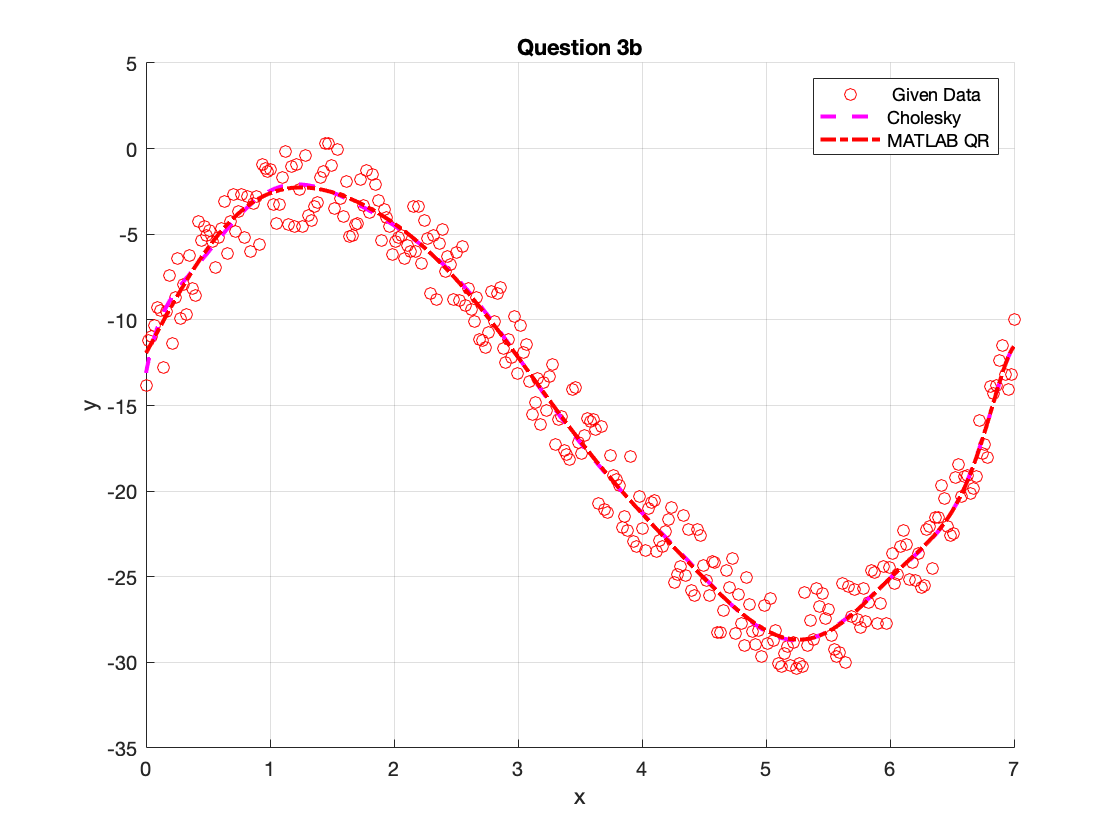


powers = 0:deg;
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
x_new = 0:0.01:7;
x_new = x_new';

fr = zeros(length(x_new),1);
fc = zeros(length(x_new),1);


for I = 1:length(powers)
   fr = fr + Ar(I)*x_new.^powers(I);   
   fc = fc + Ac(I)*x_new.^powers(I);
end
%plots
figure
hold on
plot(x,y,'ro')
plot(x_new,fc,'m--','Linewidth',2)
plot(x_new,fr,'r-.','Linewidth',2)
xlabel('x')
ylabel('y')
legend(' Given Data','Cholesky','MATLAB QR')
title('Question 3b')
grid on

A polynomial of degree 14 is linear of form mx+b. As shown by the figure titled question 3b), both Matlab QR decomposition and Cholesky decomposition fit the data well which has a sinusoidal distribution. Moreover, both decomposition methods produce the same behavior and must have reletavily error. 

d) In this part we will use limited amount of data, we will use only** 15 data points**. Use Cholesky decompositon and QR decomposition function to find the polynomial coefficients for the 14th degree polynomial. **Comment on the results obtained in figure 3, which algorithm performs better and why?**

% Load the Input Data from the provided .mat file 
disp('Question 3d')

Question 3d


load('Polynomial_Fitting_Data.mat');

% set the degree
deg =  14;
% Define powers 

x = x_given(1:20:end);
y = y_given(1:20:end);

% get Polynomial Matrix 
Mp = PolynomialMatrix(x,deg);


   
   % MATLAB QR Decomposition
   [Q,R] = qr(Mp);
   
   % Find the polynomial coefficients using L, and Q & R matrices obtained obove.
   
   % Name the Coefficeints obtained Cholesky  Ac
        % Use the MATLAB's Forward Slash Algorithm to obtain Ac 
        % by solving the normal equations (like we did in Tutorial)
            % Normal Eqautions: (Mp'*Mp)*Ac = Mp'*y
            % write your code here

   Ac = (Mp' * Mp) \ (Mp' * y)

Ac = 	1.0e+03 *

   -0.0138
   -0.1296
    0.8756
   -2.0109
    2.4112
   -1.7097
    0.7468
   -0.1977
    0.0280
   -0.0009


   % Name the Coefficeints obtained QR as Ar
            % write your code here
   Ar = (Q * R) \ y

Ar = 	1.0e+04 *

   -0.0014
   -0.1054
    0.6852
   -1.8101
    2.6740
   -2.5063
    1.5924
   -0.7123
    0.2288
   -0.0531


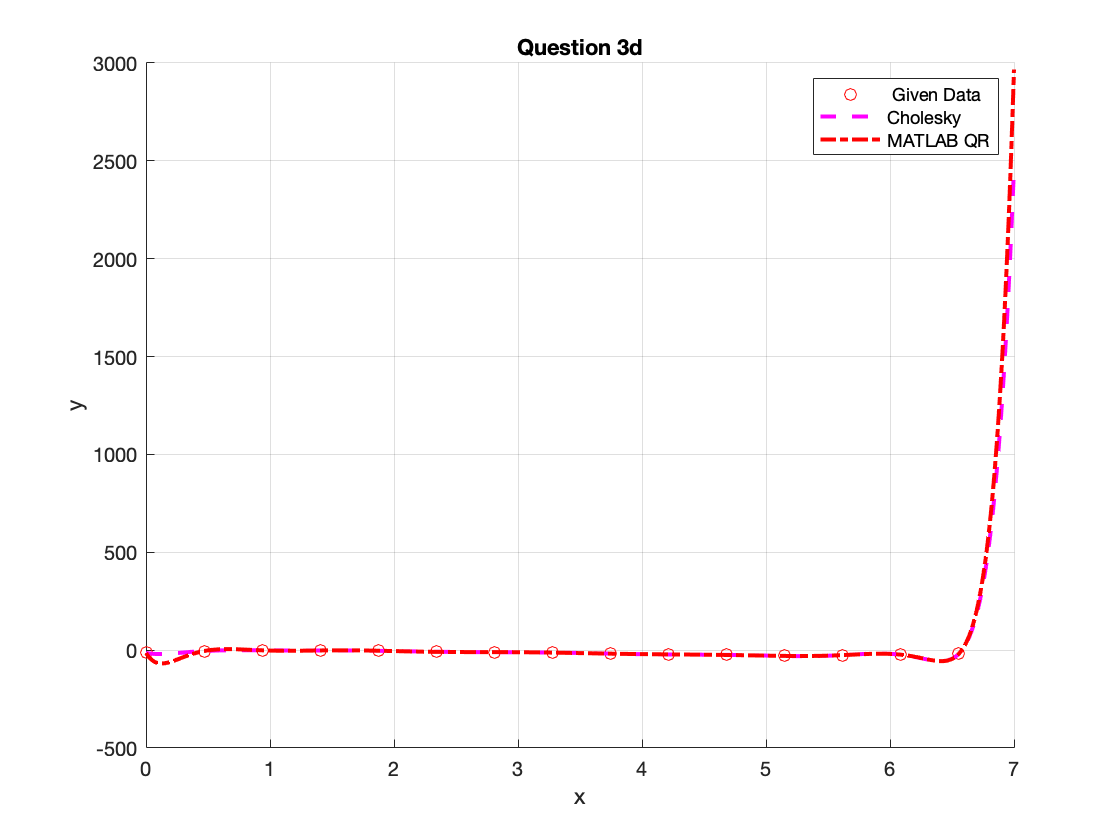

   powers = 0:deg;
   
   %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
   x_new = 0:0.01:7;
   x_new = x_new';
   
   fr = zeros(length(x_new),1);
   fc = zeros(length(x_new),1);
   
  
   for I = 1:length(powers)
       fr = fr + Ar(I)*x_new.^powers(I);   
       fc = fc + Ac(I)*x_new.^powers(I);
   end
   %plots
   figure
   hold on
   plot(x,y,'ro')
   plot(x_new,fc,'m--','Linewidth',2)
   plot(x_new,fr,'r-.','Linewidth',2)
   xlabel('x')
   ylabel('y')
   legend(' Given Data','Cholesky','MATLAB QR')
   title('Question 3d')
   grid on

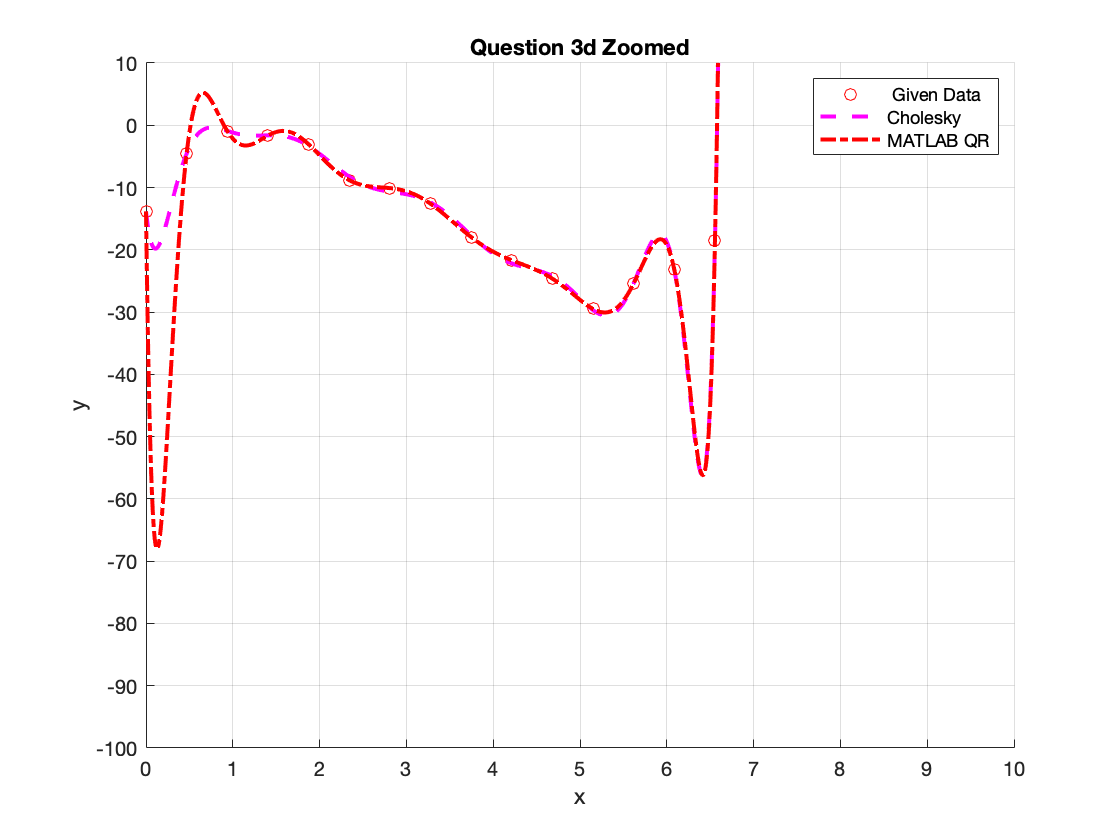

   
   figure
   hold on
   plot(x,y,'ro')
   plot(x_new,fc,'m--','Linewidth',2)
   plot(x_new,fr,'r-.','Linewidth',2)
   xlabel('x')
   ylabel('y')
   legend(' Given Data','Cholesky','MATLAB QR')
   title('Question 3d Zoomed')
   xlim([0 10])
   ylim([-100 10])
   grid on

In the plot titled question 3d, it appears that a 14th degree polynomial fits the data quite well. However, upon  inspection, its clear that the polynominal diverges, and does not fit the data for x > 6.5, since its degree is quite large. The scale of the y-axis suggests that a closer look is necessary. In the figure titled question 3d zoomed, aa 14th degree polynomial clearly overfits the 15 data points, which again are distributed relatively sinuoisadally, or at least, distributed such that they could be fit by a lower order polynomial. The line passes through each data apoint individually, but it is clear that this would be a poor regression tool for unseen data. Finally, both decomposition methods produce the same behavior and must have reletavily error. 

## Question 4:

 In this question we will develop the different algorithms to implment QR factorization.

a)  Use the cell below to implement a function that computes Gram-Schmidt based QR decompositon of a input matrix A.

*See appendix 4.a)*

  Use the cell blow to test the your method by comparing the computing the ${\left\|A-Q\;R\right\|}_F$. Use the Frobenius  norm in the MATLAB, comment on your result

disp('Question 4a)')

Question 4a)



clear norm
A = randi(100,6); % A is a 6x6 matrix of random numbers
[Q,R] = gschmidt(A)

Q =     0.3852    0.4029   -0.0101   -0.2396    0.0155   -0.7947
    0.4903   -0.4148    0.6734    0.2771    0.2316   -0.0603
    0.0560    0.7793    0.2544    0.2051    0.3869    0.3648
    0.3572   -0.1877   -0.6500    0.1575    0.6224    0.0509
    0.3432    0.1477   -0.2393    0.6845   -0.5778    0.0266
    0.6023    0.0346   -0.0435   -0.5748   -0.2744    0.4780


R =   142.7831   85.5073  147.7206   82.4538  143.6865  114.8666
         0   72.1283   78.1496  -11.9704   72.8528   56.6499
         0         0   38.6038    0.2684   11.3492  -54.0189
         0         0         0   66.5208   18.0926   17.0689
         0         0         0         0   48.0158   43.1185
         0         0         0         0         0   19.1277



norm = norm(A-Q*R,'fro')

norm = 1.9132e-14

b)  Use the cell below to implement a function that uses the Modiefied Gram-Schmidt approach to compute the  QR decompositon of  the input matrix A.

*See appendix 4b)*

  Use the cell blow to test the your method by comparing the computing the ${\left\|A-Q\;R\right\|}_F$. Use the Frobenius  norm in the MATLAB, comment on your result.

disp('Question 4b)')

Question 4b)



clear norm
A = randi(100,6); % A is a 6x6 matrix of random numbers
[Q,R] = gschmidt(A)

Q =     0.4828   -0.3376    0.3003    0.3937   -0.6361   -0.0556
    0.1851    0.8625    0.3448   -0.1801   -0.2628   -0.0368
    0.5392   -0.2723    0.4006   -0.5642    0.3863    0.0842
    0.1288    0.0960   -0.0890    0.1790    0.0310    0.9661
    0.6277    0.1713   -0.7376    0.0065    0.0564   -0.1716
    0.1770    0.1711    0.2804    0.6798    0.6106   -0.1603


R =   124.2658   82.0740   70.8562  144.2231  117.4659  100.2045
         0   67.0213   64.1222   49.2386   13.4151   21.3187
         0         0   48.0807   14.1975  -13.0487  -24.1284
         0         0         0   78.0494    1.3508   53.1594
         0         0         0         0    5.9752   57.0258
         0         0         0         0         0   28.5923



norm = norm(A-Q*R,'fro')

norm = 2.3832e-14

c)  Use the cell below to implement a function that uses the Householder approach to compute the  QR decompositon of  the input matrix A.

*See appendix 4c)*

  Use the cell blow to test the your method by comparing the computing the ${\left\|A-Q\;R\right\|}_F$. Use the Frobenius  norm in the MATLAB, comment on your result.

disp('Question 4c')

Question 4c



clear norm
A = randi(100,6); % A is a 6x6 matrix of random numbers
[Q,R] = householder(A)

Q =    -0.0300    0.7836    0.2397    0.0726    0.4545   -0.3403
   -0.3794   -0.0632    0.5535    0.1704    0.2651    0.6682
   -0.4992   -0.0190   -0.7236    0.0680    0.4571    0.1154
   -0.4693   -0.4057    0.3206   -0.4521    0.1780   -0.5257
   -0.0499    0.3610   -0.0994   -0.8340   -0.1655    0.3666
   -0.6190    0.2945   -0.0023    0.2472   -0.6747   -0.1172


R =  -100.1549  -90.8193 -137.2974  -72.0484 -182.0580 -119.1255
    0.0000   70.5468   13.2642   10.3139   52.7254   66.7373
    0.0000    0.0000  -43.8235    4.1499   16.9645   10.0821
   -0.0000   -0.0000    0.0000  -99.6315  -24.5385  -77.9075
    0.0000    0.0000    0.0000   -0.0000   41.6890  -28.6953
   -0.0000    0.0000    0.0000    0.0000         0  -12.9849



norm = norm(A-Q*R,'fro')

norm = 1.3377e-13

d) We know that $\mathit{\mathbf{Q}}$ matrix obtained using QR decompostion should have orthonormal columns i.e. ${\mathit{\mathbf{Q}}}^{\mathit{\mathbf{T}}} \mathit{\mathbf{Q}}=\mathit{\mathbf{I}}$. However, due to numerical errors, In this section we will test the functions written above to compare the error between the above implemeneted approaches. In oder to do this we will use a $n\times n$ HIlbert Matrix, the entries of Hibert Matrix are given by 


$$h_{i,j} =\frac{1}{\;i+j-1}$$


 In the cell below we compute the QR decomposition of Hilbert matrices of size ranging from 2 to 16, then we compute the norm of error $\left({\mathit{\mathbf{Q}}}^{\mathit{\mathbf{T}}} \mathit{\mathbf{Q}}-\mathit{\mathbf{I}}\right)$ to assess the performance of the lorithms written in part (a), ( b), and (c). Comment on the results obtained.

disp('Question 4d)')

Question 4d)


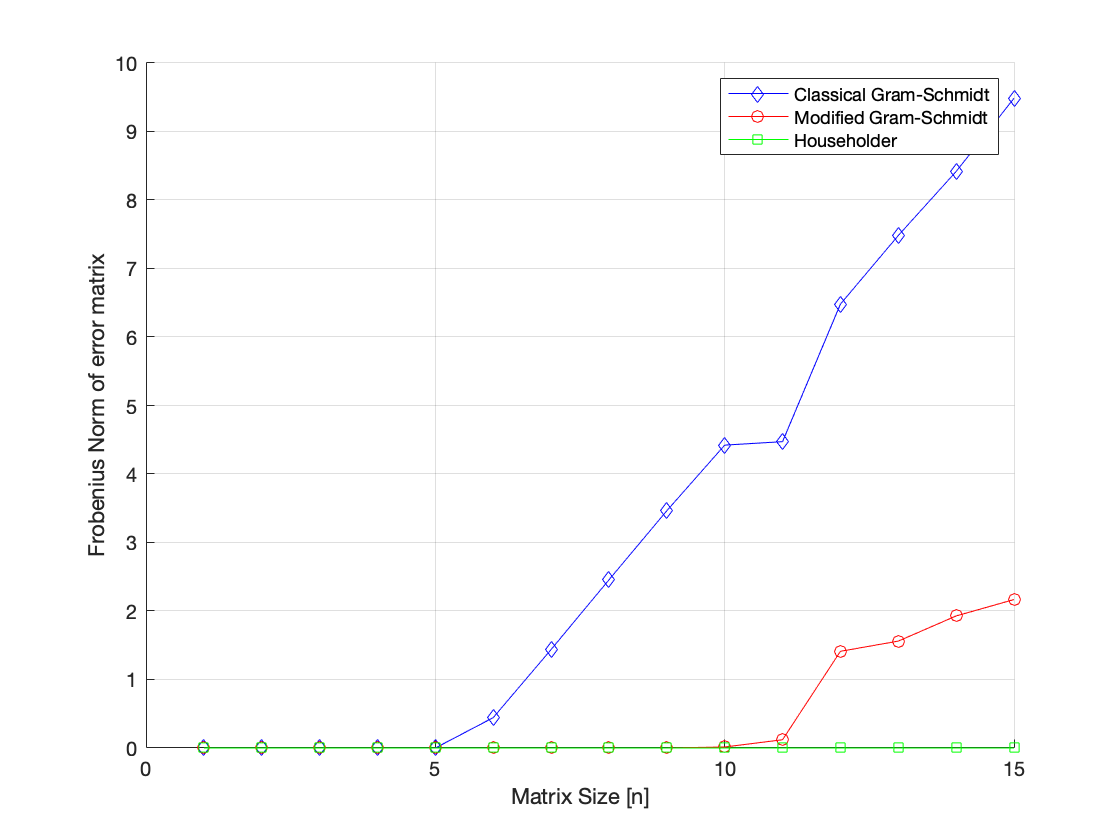


clear norm
for n=2:16
    a= hilb(n); % n is the size of the matrix
    [q_gs,r1] = gschmidt(a); %using algorithm classical Gram--Schmidt
    [q_mgs,r2] = mgschmidt(a); %using algorithm modified Gram-Schmidt
    [q_hh,r3] = householder(a); % using house holder
    
    err_gs(n-1) = norm(q_gs'*q_gs - eye(n),'fro');
    err_mgs(n-1) = norm(q_mgs'*q_mgs - eye(n),'fro');
    err_hh(n-1) = (norm(q_hh'*q_hh - eye(n),'fro'));
end 

figure
hold on 
grid on 
plot(err_gs,'b-d')
plot(err_mgs,'r-o')
plot(err_hh,'g-s')
ylabel('Frobenius Norm of error matrix');
xlabel('Matrix Size [n]')
legend('Classical Gram-Schmidt','Modified Gram-Schmidt','Householder');

As the dimension of the matrix increases, the norm error increases for QR decomposition using Grant Schmidt and modified Grant Schimdt, albeit, the latter increases more slowly. Conversely, the error produced by the householder decomposition does not appear to increase. 

e) Finally, now we have implemented various different versions of QR decompositon. Use above versions of the the QR transform and use this to fit the polynomial in question 3. We want to fit the polynomial of degree 14 through the data with 15 points. Clearly show all the plots (with legends) and comment on the results obtained.

disp('Question 4e')

Question 4e


load('Polynomial_Fitting_Data.mat');

% set the degree
deg =  14;
% Define powers 

x = x_given(1:20:end);
y = y_given(1:20:end);

% get Polynomial Matrix 
Mp = PolynomialMatrix(x,deg);

% MATLAB QR Decomposition

% MATLAB QR Decomposition
[Qgs,Rgs] = gschmidt(Mp);
[Qmgs, Rmgs] = mgschmidt(Mp);
[Qh, Rh] = householder(Mp);
   
Ags = Rgs \ Qgs' * y ;
Amgs = Rmgs \ Qmgs' *  y;
Ah = Rh \ Qh' *  y;

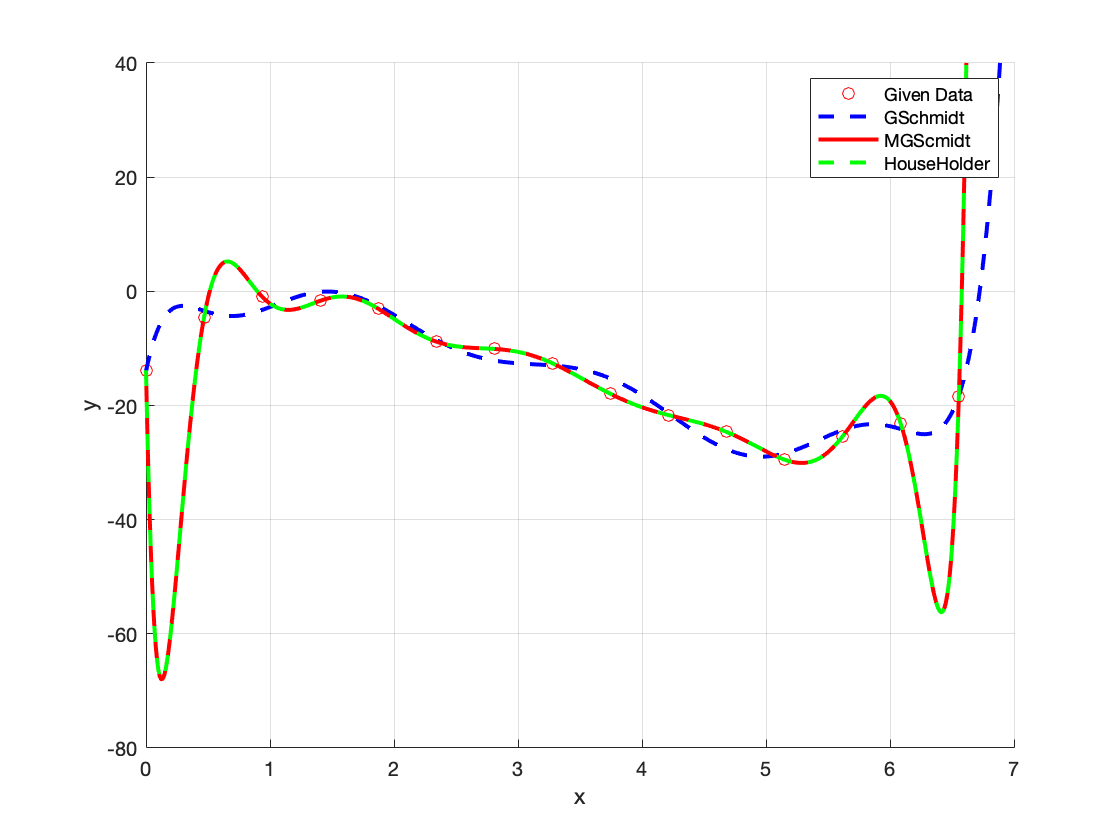


powers = 0:deg;

x_new = 0:0.01:7;
x_new = x_new';

fr = zeros(length(x_new),1);
fc = zeros(length(x_new),1);
fl = zeros(length(x_new),1);


for I = 1:length(powers)
   fr = fr + Ags(I)*x_new.^powers(I);   
   fc = fc + Amgs(I)*x_new.^powers(I);
   fl = fl + Ah(I)*x_new.^powers(I);
end
%plots   
figure
hold on;
plot(x,y,'ro')

hold on;
plot(x_new,fr,'b--','Linewidth',2)

hold on;
plot(x_new,fc,'r-','Linewidth',2)

hold on;
plot(x_new,fl,'g--','Linewidth',2)

xlabel('x')
ylabel('y')
legend('Given Data','GSchmidt','MGScmidt','HouseHolder')
xlim([0 7])
ylim([-80 40])
grid on

 Clearly, the modified Grant Schmidt and the householder algorithms overfit the data, while the classical Grant Schmidt fits the data quite well and is likley to generalize well to more datapoints within the domain 0<x<6.5. This is likely because this algorithm is less focused on minimizing error. The error it produces allows it to generalize better for new data. 

## Appendix 1

function A = Hilbert_matrix(size)
A = zeros(size,size);

for i=1:size
    for j=1:size
        A(i,j) = 1/(i+j-1);
    end 
end 

end

2a) Cholesky Decompositon

function L = CholeskyDecomposition(M)
    if(size(M,1) ~= size(M,2))
        disp('Matrix M must be square!'); 
    end
    L = zeros(size(M));
    for i = 1:size(M) %rows
      diff_square = 0;
      for j = 1:i-1 %cols 
        diff =  sum(L(i,1:j-1) .* L(j,1:j-1));
        L(i,j) = (M(i,j) - diff) / L(j,j);
        diff_square = diff_square + L(i,j)^2;
      end
      L(i,i) = sqrt(M(i,i) - diff_square);
    end
    L = real(L);
end

2b) Least Square Solver 

function x = LeastSquareSolver_Cholesky(A,b)
M = A'* A;
L = CholeskyDecomposition(M);
y = forward_sub(L, A' * b);
x = backward_sub(L', y);
end


function x = LeastSquareSolver_Cholesky2(A,b)
M = A'* A;
L = CholeskyDecomposition(M);
y = inv(L)*transpose(A) * b ;
x = inv(transpose(L)) * y;
end


function y = forward_sub(L, b)
    n = size(b); %dimension
    y = zeros(n); 
    for i = 1:n  %iterate over each row
        y(i) = b(i); %initialize y to b
        for j = 1:i-1 %get y from previous y
            if i ~= 0  %except if first y
              y(i) =  y(i) - y(j)*L(i,j);
            end
        end
        y(i) = y(i) / L(i,i);
    end
end


function X = backward_sub(U, y)
    n = size(y); %dimension
    X = zeros(n); 
    for i = n :-1:1 %iterate over each row backwards
        X(i) = y(i); %initialize X to y
        if i ~= n  %except if last X
            for j = i+1:n %get X from previous X
              X(i) =  X(i) - X(j) * U(i,j);
            end
        end
        X(i) = X(i) / U(i,i);
    end
end

3a) Polynomial Matrix

function M = PolynomialMatrix(x,n)
 M = zeros(size(x,1), n+1);
 for i=1:size(M)
     M(i,:) = x(i);
     M(i, :) = M(i, :) .^ (0:1:n);
 end
end

4a) Grant Schmidt

function [Q,R] = gschmidt(A)
    [m,n] = size(A);
    R = zeros(n,n);
    Q = zeros(m,n);
    for j = 1:n
        v = A(:,j);  
        for i = 1:(j-1)
            R(i,j) = transpose(Q(:,i)) * A(:,j);
            v = v - R(i,j) * Q(:,i);
        end
        R(j,j) = norm(v);
        Q(:,j) = v / R(j,j);
    end
end

4b) Modified Grant Schmidt

function [Q,R] = mgschmidt(A)
    [m,n] = size(A);
    R = zeros(n,n);
    Q = zeros(m,n);
    V = zeros(m,n);
    for i = 1:n
        V(:,i) = A(:,i);
    end
    for i = 1:n
        R(i,i) = norm(V(:,i));
        Q(:,i) = V(:,i) / R(i,i);
        for j = (i+1):n
            R(i,j) = transpose(Q(:,i)) * V(:,j);
            V(:,j) = V(:,j) - R(i,j) * Q(:,i);
        end
    end
end

4c) 

function [Q,R] = householder(A)
    [m,n] = size(A);
    Q = eye(m);
    R = A;
    for j = 1:n
         l2 = norm(R(j:m, j));
         s = -sign(R(j, j));
         u = R(j, j) - s*l2;
         w = R(j:m, j)/u;
         w(1) = 1;
         t = -s*u/l2;
         
         R(j:m, :) = R(j:m, :) - (t*w)*(w'*R(j:m,:));
         Q(:, j:m) = Q(:, j:m) - (Q(:, j:m) * w) * (t*w)';
    end 
end